%closing
clc; close all;
image=[0 0 0 0 0 0 0 0;
        0 0 1 1 1 1 0 0;
        0 0 1 1 1 1 0 0;
        0 0 0 1 1 0 0 0;
        0 0 0 1 1 0 0 0;
        0 0 1 1 1 1 0 0;
        0 0 1 1 1 1 0 0;
        0 0 0 0 0 0 0 0];
se=[1 1 1; 1 1 1; 1 1 1];
%dilation
image=padarray(image,[1,1],0)

image =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     1     1     0     0     0     0
     0     0     0     0     1     1     0     0     0     0
     0     0     0     1     1     1     1     0     0     0
     0     0     0     1     1     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


figure
subplot(1,2,1)
imshow(image)
[m,n]=size(image)

m = 10

n = 10

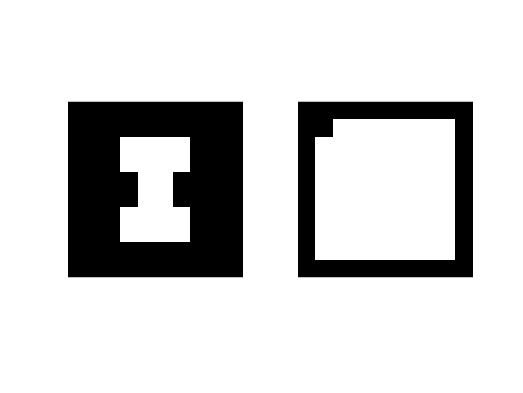

for i=2:m-1
   for j=2:n-1
         if se(1,1)*image(i-1,j-1)==1 || se(1,2)*image(i-1,j)==1 || ...
                        se(1,3)*image(i-1,j+1)==1 || se(2,1)*image(i,j-1)==1 || ...
                        se(2,2)*image(i,j)==1 || se(2,3)*image(i,j+1)==1 || ...
                        se(3,1)*image(i+1,j-1)==1 || se(3,2)*image(i+1,j)==1 || ...
                        se(3,3)*image(i+1,j+1)==1

                    image(i,j)=1;
         else
             image(i,j)=0;
        end
   end
end
subplot(1,2,2)
imshow(image)


%erosion
image1=image;
[m1,n1]=size(image1)

m1 = 10

n1 = 10

figure
subplot(1,2,1)
imshow(image1)
for i=2:m1-1
   for j=2:n1-1
                if se(1,1)*image1(i-1,j-1)==1 && se(1,2)*image1(i-1,j)==1 && ...
                        se(1,3)*image1(i-1,j+1)==1 && se(2,1)*image1(i,j-1)==1 && ...
                        se(2,2)*image1(i,j)==1 && se(2,3)*image1(i,j+1)==1 && ...
                        se(3,1)*image1(i+1,j-1)==1 && se(3,2)*image1(i+1,j)==1 && ...
                        se(3,3)*image1(i+1,j+1)==1
                    image1(i,j)=1;
                else
                    image1(i,j)=0;
        end
   end
end
image1

image1 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


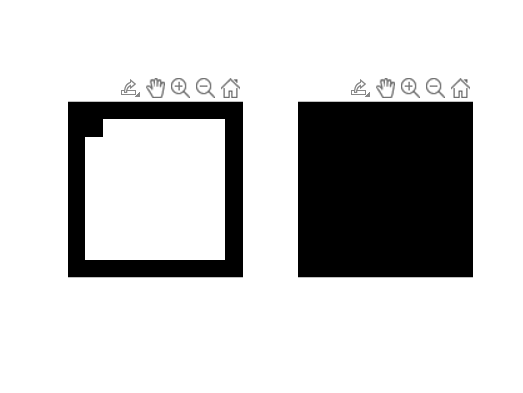

subplot(1,2,2)
imshow(image1)